# Diagnostic Plots

Here, we will analyze the output of a simulation from **cell_cycle_model.m** and produce various plots from Figures 2, 3 and 4.

First, we load the workspace.

load_path = strcat(pwd);
load(strcat(load_path,"/sim_workspace.mat"))
analysis_path = strcat(pwd,'/analysis');

%if ~exist(analysis_path,'dir')
%    mkdir(analysis_path)
%end

% Plotting parameters
color_g1 = [0.6350 0.0780 0.1840];%'#A2142F';
color_g2 = [0 0.4470 0.7410];%'#0072BD';
color_cycle = [0.4940 0.1840 0.5560];%'#7E2F8E';
color_full = [0.4660 0.6740 0.1880];%'#77AC30';
color_START = [0.8500 0.3250 0.0980];%'#D95319';
color_bud = [0,0,153/256];

new_color_d1 = [0 84/255 147/255];%'#005493';
new_color_d2 = [149/255 177/255 231/255];%'#95B1E7';
new_color_m1 = [255/255 147/255 0];%'#FF9300';
new_color_m2 = [255/255 212/255 121/255];%'#FFD479';
new_color_all = [216/255 27/255 88/255];%[77/255 139/255 96/255];%'#4D8B60';
new_color_START = [216/255 27/255 88/255];%'#008F00';
new_color_div_d = [0/255, 77/255, 46/255];%[181/255 23/255 0];%'#B51700';
new_color_div_m = [117/255, 225/255, 225/255];%[152/255 59/255 201/255];%'#983BC9';
new_color_psg1_d = [0 0 0];%'#FFFFFF';
new_color_psg1_m = [146/255 146/255 146/255];%'#929292';

ax_label_size = 32;
ax_ticklabel_size = 28;
ax_line_width = 3;

line_width_thick = 4;
line_width_slim = 2;
face_alpha = 0.2;
legend_label_size = 28;
title_label_size = 34;

## Population volume over time 

Mothers & daughters anywhere in the cell cycle. Check steady state condition.

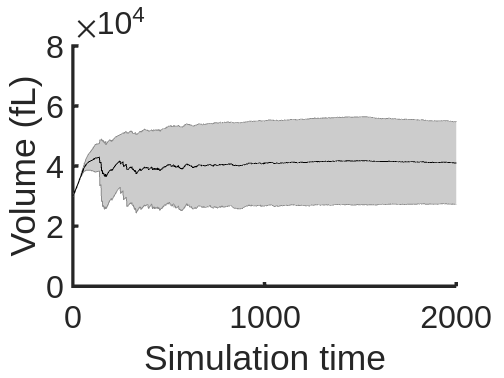

figure('Name','Volume')
hold on
shadedErrorBar(1:start_phase_length,pop_vol_mean,pop_vol_sigma)
ylim([-0.5 8e4])
xlabel('Simulation time','FontSize',ax_label_size)
ylabel('Volume (fL)','FontSize',ax_label_size)
set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size)
%saveas(gcf,strcat(analysis_path,'/pop_volume_over_time.png'))
hold off

## Average cell cycle stage over time

Ensuring steady-state is reached.

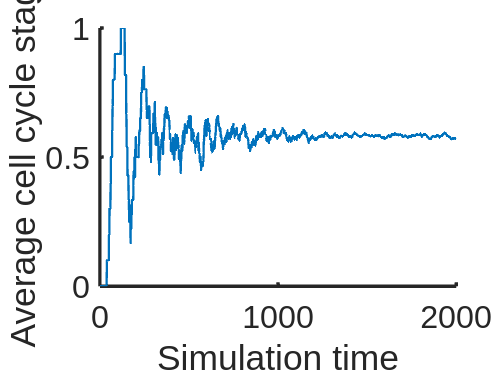

figure('Name','Cell Cycle Synchrony')
hold on
plot(1:start_phase_length,pop_cell_cycle,'LineWidth',line_width_slim)
xlabel('Simulation time','FontSize',ax_label_size)
ylabel('Average cell cycle stage','FontSize',ax_label_size)
set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size)
%saveas(gcf,strcat(analysis_path,'/cell_cycle_synchrony.png'))
hold off

## Full size distribution

Including mothers & daughters anywhere in the cell cycle. 

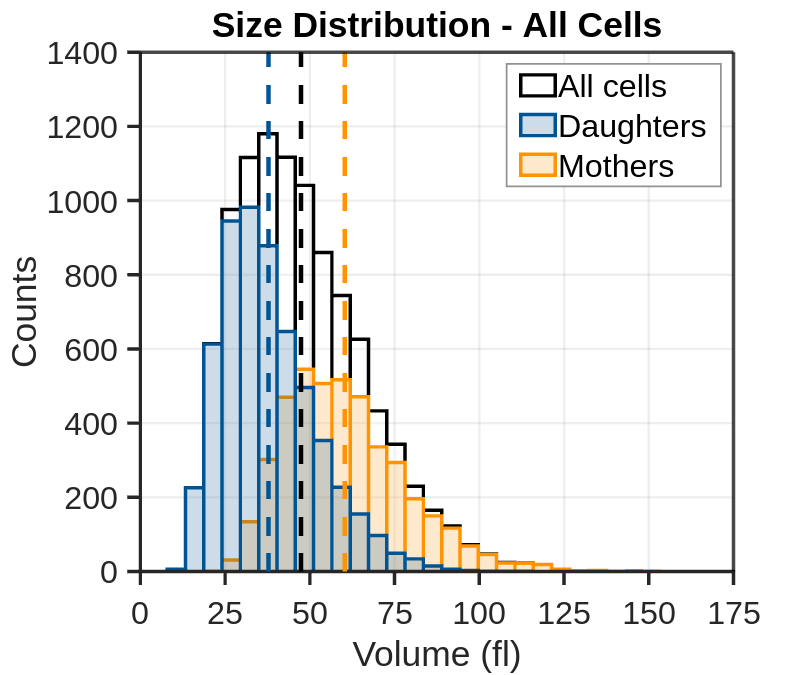

mean_size_full = mean(cell_v(:,length(cell_v(1,:))) + cell_bud(:,length(cell_v(1,:))));
std_size_full = std(cell_v(:,length(cell_v(1,:))) + cell_bud(:,length(cell_v(1,:))));
if mean_size_full ~= 0
    cv_size_full = std_size_full/mean_size_full;
else
    cv_size_full = 0;
end

size_full_daughters = [];
size_full_mothers = [];
for i = 1:length(mother_daughter(:,end))
    if mother_daughter(i,end) == 1
        size_full_mothers(i) = cell_v(i,length(cell_v(1,:))) + cell_bud(i,length(cell_v(1,:)));    
    else
        size_full_daughters(i) = cell_v(i,length(cell_v(1,:))) + cell_bud(i,length(cell_v(1,:))); 
    end 
end
size_full_daughters = size_full_daughters(size_full_daughters~=0);
size_full_mothers = size_full_mothers(size_full_mothers~=0);

mean_size_daughters_end = mean(size_full_daughters);
std_size_daughters_end = std(size_full_daughters);
if mean_size_daughters_end ~= 0
    cv_size_daughters_end = std_size_daughters_end/mean_size_daughters_end;
else
    cv_size_daughters_end = 0;
end

mean_size_mothers_end = mean(size_full_mothers);
std_size_mothers_end = std(size_full_mothers);
if mean_size_mothers_end ~= 0
    cv_size_mothers_end = std_size_mothers_end/mean_size_mothers_end;
else
    cv_size_mothers_end = 0;
end

n_cell_tot = length(cell_v(:,end));
n_cell_daughters = length(size_full_daughters);
n_cell_mothers = length(size_full_mothers);

format long

xmin = 0.25e1;
xmax = 20e1;
bins = xmin:2.16*xmin:xmax;

[p_size_full,~] = histcounts((cell_v(:,length(cell_v(1,:))) + cell_bud(:,length(cell_v(1,:))))/1e3,bins,'Normalization',['count']);
[p_size_full_daughters,~] = histcounts((size_full_daughters)/1e3,bins,'Normalization','probability');
[p_size_full_mothers,~] = histcounts((size_full_mothers)/1e3,bins,'Normalization','probability');

JS_div_MD_full = JS_div(p_size_full_daughters,p_size_full_mothers);

figure('Name','Size Distribution - All Cells','Position', [0 0 900 750])
h1 = histogram((cell_v(:,length(cell_v(1,:))) + cell_bud(:,length(cell_v(1,:))))/1e3,...
    bins,...
    'FaceAlpha',face_alpha,'FaceColor','White','EdgeColor','k',...
    'LineWidth',line_width_thick-1,'Normalization','count');
hold on


h2=histogram((size_full_mothers)/1e3,...
    h1.BinEdges,...
    'FaceAlpha',face_alpha,'FaceColor',new_color_m1,'EdgeColor',new_color_m1,...
    'LineWidth',line_width_thick-1,'Normalization','count');
h3=histogram((size_full_daughters)/1e3,...
    h1.BinEdges,...
    'FaceAlpha',face_alpha,'FaceColor',new_color_d1,'EdgeColor',new_color_d1,...
    'LineWidth',line_width_thick-1,'Normalization','count');
xline(mean_size_full/1e3,'Color','k','LineWidth',line_width_thick,...
    'LineStyle','--','Alpha',1)
xline(mean_size_daughters_end/1e3,'Color',new_color_d1,'LineWidth',line_width_thick,...
    'LineStyle','--','Alpha',1)
xline(mean_size_mothers_end/1e3,'Color',new_color_m1,'LineWidth',line_width_thick,...
    'LineStyle','--','Alpha',1)
xlabel('Volume (fl)','FontSize',ax_label_size)
ylabel('Counts','FontSize',ax_label_size) 
xlim([0 175])
xticks(0:25:175)
ylim([0,1400])
title('Size Distribution - All Cells','Fontsize',title_label_size)
set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size)
set(gca,'TickDir','out');
set(gca,'TickLength',[0.02 0]);
set(gca,"Box",'off')
xline(gca().XLim(2),'LineWidth',ax_line_width,'Color','k')
yline(gca().YLim(2),'LineWidth',ax_line_width,'Color','k')
l = legend([h1,h3,h2],{'All cells','Daughters','Mothers'},'Fontsize',legend_label_size);
%legend('boxon')
set(l,'LineWidth',1.5,'EdgeColor',new_color_psg1_m)
set(l,'Position',[l.Position(1)*0.99 l.Position(2)*0.99 l.Position(3)*1.01 l.Position(4)*1.01])
%{
legend({strcat('All cells, N cells tot. = ',num2str(n_cell_tot), ...
', JS Div. (M,D) = ',num2str(JS_div_MD_full,'%0.3g')), ...
  strcat('Daughters, N cells = ',num2str(n_cell_daughters)),  ...
  strcat('Mothers, N cells = ',num2str(n_cell_mothers)), ...
  strcat('Full, Mean= ',num2str(mean_size_full,'%0.3g'), ...
', CV = ',num2str(cv_size_full,'%0.3g')), ...
  strcat('Daughters, Mean = ',num2str(mean_size_daughters_end,'%0.3g'),', CV = ',num2str(cv_size_daughters_end,'%0.3g')), ...
    strcat('Mothers, Mean = ',num2str(mean_size_mothers_end,'%0.3g'),', CV = ',num2str(cv_size_mothers_end,'%0.3g'))},...
    'Fontsize',legend_label_size)
%}
grid on
set(gca,'GridAlpha',0.08,'GridLineWidth',line_width_slim)

%saveas(gcf,strcat(analysis_path,'/new_size_dist_full.png'))
hold off

clear gca

## Processing daughters from 1st or 2nd gen (if not done before)

size_at_birth_from_mother = [];
size_at_birth_from_daughter = [];
size_at_start_from_mother = [];
size_at_start_from_daughter = [];
size_at_cytokinesis_from_mother = [];
size_at_cytokinesis_from_daughter = [];

for i = 1:length(M_D_at_birth_processed)
    if M_D_at_birth_processed(i) == 1
        size_at_start_from_mother(i) = volume_at_START(i);
        size_at_birth_from_mother(i) = size_at_birth(i);
        size_at_cytokinesis_from_mother(i) = size_at_birth(i)+cell_cycle_growth(i);
    else
        size_at_start_from_daughter(i) = volume_at_START(i);
        size_at_birth_from_daughter(i) = size_at_birth(i);
        size_at_cytokinesis_from_daughter(i) = size_at_birth(i)+cell_cycle_growth(i);
    end 
end


size_at_birth_from_mother = size_at_birth_from_mother(size_at_birth_from_mother~=0);
size_at_birth_from_daughter = size_at_birth_from_daughter(size_at_birth_from_daughter~=0);
size_at_start_from_mother = size_at_start_from_mother(size_at_start_from_mother~=0);
size_at_start_from_daughter = size_at_start_from_daughter(size_at_start_from_daughter~=0);
size_at_cytokinesis_from_mother = size_at_cytokinesis_from_mother(size_at_cytokinesis_from_mother~=0);
size_at_cytokinesis_from_daughter = size_at_cytokinesis_from_daughter(size_at_cytokinesis_from_daughter~=0);

## Daughter size at START

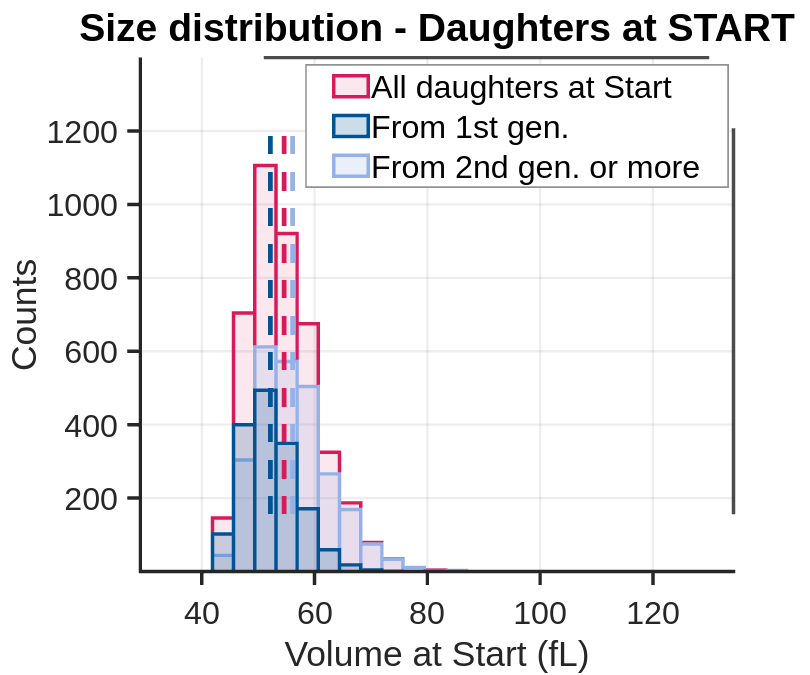

     3.860960241344764e+04



     8.891961575011710e+03



   0.230304406654927



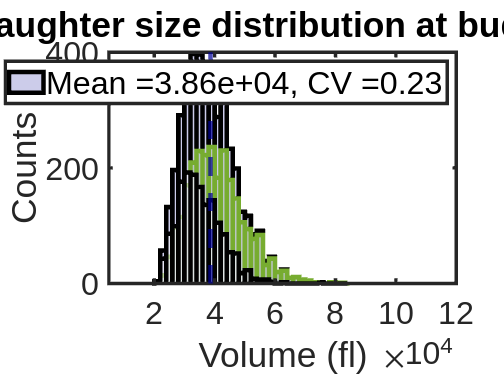

     6.210419341740948e+04



     1.359291929680802e+04



   0.218872809529116



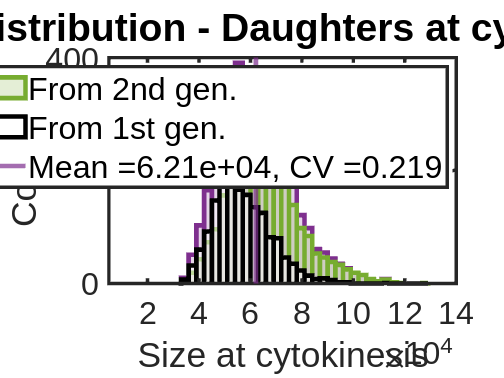

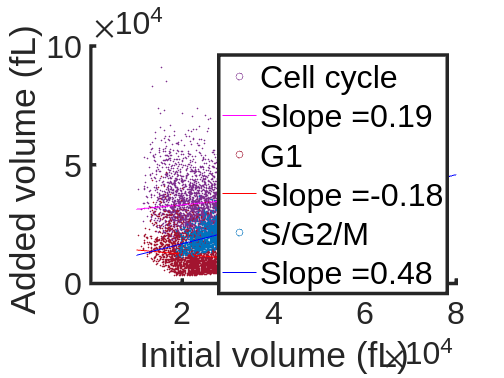

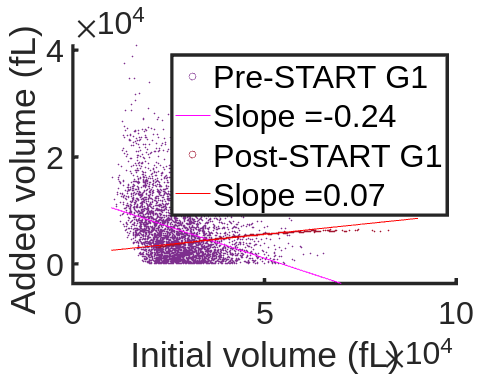

analysis_path = '/home/felix/Documents/Codes/analysis/parameter_direction/ppv'

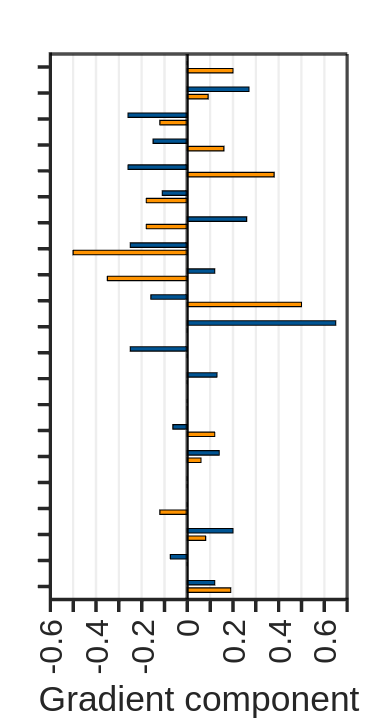

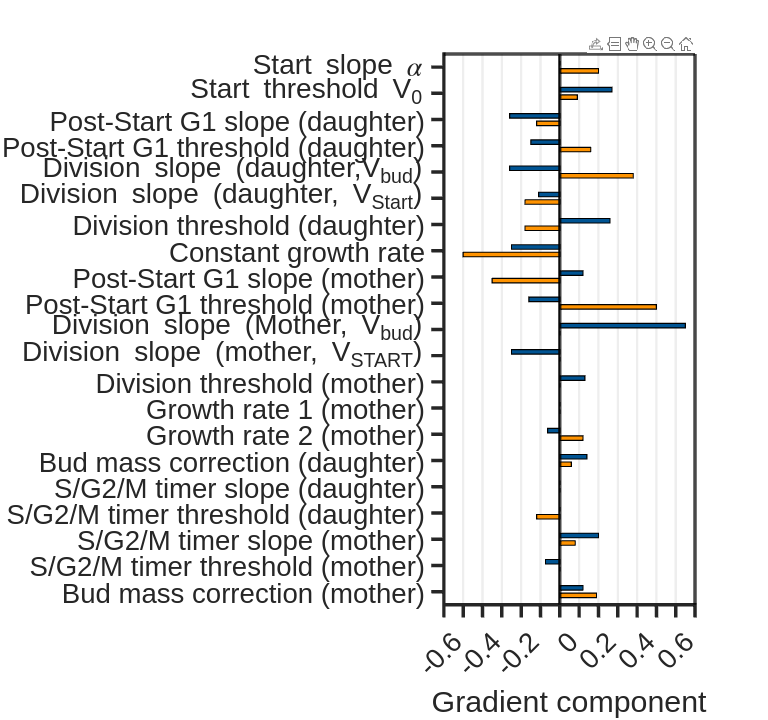

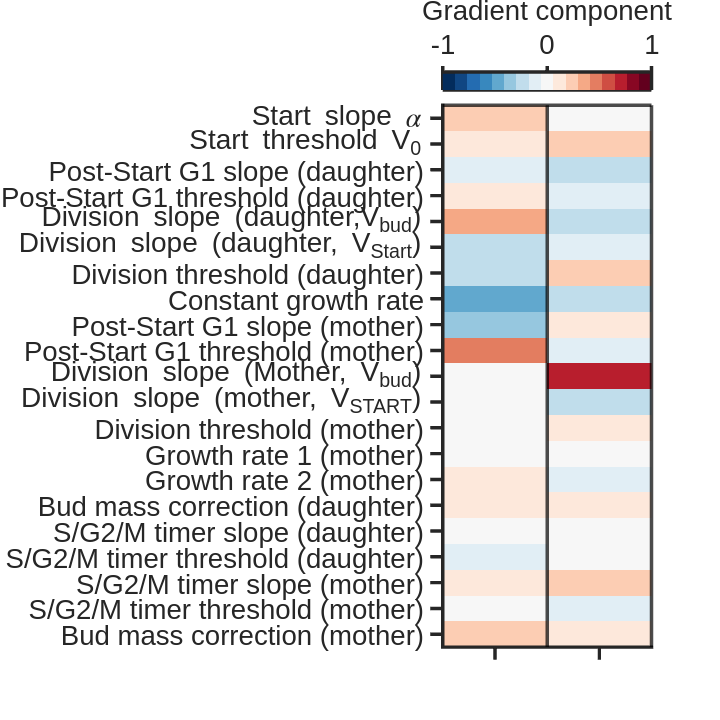

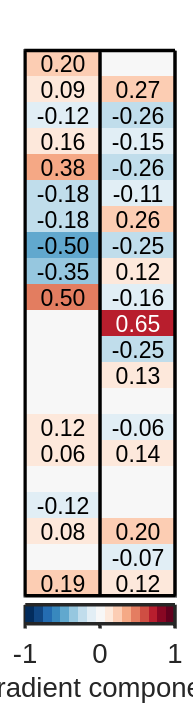

mean_size_START = mean(volume_at_START);
std_size_START = std(volume_at_START);
if mean_size_START ~= 0
    cv_size_START = std_size_START/mean_size_START;
else
    cv_size_START = 0;
end


mean_size_start_from_daughters = mean(size_at_start_from_daughter);
std_size_start_from_daughters = std(size_at_start_from_daughter);
if mean_size_start_from_daughters ~= 0
    cv_size_start_from_daughters = std_size_start_from_daughters/mean_size_start_from_daughters;
else
    cv_size_start_from_daughters = 0;
end

mean_size_start_from_mothers = mean(size_at_start_from_mother);
std_size_start_from_mothers = std(size_at_start_from_mother);
if mean_size_start_from_mothers ~= 0
    cv_size_start_from_mothers = std_size_start_from_mothers/mean_size_start_from_mothers;
else
    cv_size_start_from_mothers = 0;
end

n_cell_start = length(volume_at_START);
n_cell_start_from_daughters = length(size_at_start_from_daughter);
n_cell_start_from_mothers = length(size_at_start_from_mother);

xmin = 0.2e1;
xmax = 12e1;
bins_START = xmin:2.5*xmin:xmax;

[p_size_start,~] = histcounts(volume_at_START/1e3,bins_START,'Normalization','Count');
[p_size_start_from_daughters,~] = histcounts(size_at_start_from_daughter/1e3,bins_START,'Normalization','probability');
[p_size_start_from_mothers,~] = histcounts(size_at_start_from_mother/1e3,bins_START,'Normalization','probability');

JS_div_D1D2_start = JS_div(p_size_start_from_daughters,p_size_start_from_mothers);

figure('Name', 'Size at Start','Position', [0 0 900 750])
h1=histogram(volume_at_START/1e3,bins_START,'FaceAlpha',face_alpha-0.1,'Normalization','Count' ,...
    'FaceColor',new_color_all,'EdgeColor',new_color_all,'LineWidth',line_width_thick-1);
hold on
h2=histogram(size_at_start_from_mother/1e3,h1.BinEdges,'FaceColor',new_color_d2,...
    'Normalization','Count','FaceAlpha',face_alpha,'LineWidth',line_width_thick-1,...
    'EdgeColor',new_color_d2);
h3=histogram(size_at_start_from_daughter/1e3,h1.BinEdges,'FaceColor',new_color_d1,...
    'Normalization','Count','FaceAlpha',face_alpha,'LineWidth',line_width_thick-1,...
   'EdgeColor',new_color_d1);

xline(mean_size_START/1e3,'Color',new_color_all,'LineWidth',line_width_thick,'LineStyle','--','Alpha',1)
xline(mean_size_start_from_mothers/1e3,'Color',new_color_d2,'LineWidth',line_width_thick,'LineStyle','--','Alpha',1)
xline(mean_size_start_from_daughters/1e3,'Color',new_color_d1,'LineWidth',line_width_thick,'LineStyle','--','Alpha',1)
xlabel('Volume at Start (fL)','FontSize',ax_label_size)
ylabel('Counts','FontSize',ax_label_size)
set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size)
set(gca,'TickDir','out');
set(gca,'TickLength',[0.02 0]);

xlim([0 140])
xticks(0:20:140)
ylim([0,1400])%ylim([0,1400])

set(gca,"Box",'off')
xline(gca().XLim(2),'LineWidth',ax_line_width,'Color','k')
yline(gca().YLim(2),'LineWidth',ax_line_width,'Color','k')
title('Size distribution - Daughters at START','FontSize',title_label_size)
%{
legend({strcat('All daughters, N cells = ',num2str(n_cell_start), ...
', JS Div. (D1,D2) = ',num2str(JS_div_D1D2_start,'%0.3g')), ...
  strcat('From 2nd gen., N cells = ',num2str(n_cell_start_from_mothers)),  ...
  strcat('From 1st gen., N cells = ',num2str(n_cell_start_from_daughters)), ...
  strcat('All, Mean= ',num2str(mean_size_START,'%0.3g'), ...
', CV = ',num2str(cv_size_START,'%0.3g')), ...
  strcat('From 2nd gen., Mean = ',num2str(mean_size_start_from_mothers,'%0.3g'),', CV = ',num2str(cv_size_start_from_mothers,'%0.3g')), ...
    strcat('From 1st gen., Mean = ',num2str(mean_size_start_from_daughters,'%0.3g'),', CV = ',num2str(cv_size_start_from_daughters,'%0.3g'))},...
    'Fontsize',legend_label_size)
%}
l = legend([h1,h3,h2],{'All daughters at Start','From 1st gen.',['From 2nd gen. or more']},'Fontsize',legend_label_size);
set(l,'LineWidth',1.5,'EdgeColor',new_color_psg1_m)
set(l,'Position',[l.Position(1)*0.999 l.Position(2)*0.999 l.Position(3)*1.01 l.Position(4)*1.01])
grid on
set(gca,'GridAlpha',0.08,'GridLineWidth',line_width_slim)
%saveas(gcf,strcat(analysis_path,'/new_size_dist_START.png'))
hold off

### KL divergence

function div = KL_div(p,q)
    div = 0;
    for i = 1:length(p)
        if p(i) == 0
            continue
        elseif q(i) == 0
            disp('Problem with Q(i) == 0, review validity')
            break
        else
            div = div + p(i)*log2(p(i)/q(i));
        end
    end
end

### Jensen-Shannon Divergence

function div2 = JS_div(p,q)
    m = 0.5*(p+q);
    div2 = 0.5*KL_div(p(m~=0),m(m~=0)) + 0.5*KL_div(q(m~=0),m(m~=0));
end